**                                                                                                            APPLIED LINEAR CONTROLS FINAL PROJECT**

**                                                                                                                                     ROHIT MURALI**

**Section 1**. Before you can use the discrete state-space model from the Midterm Project for a state-feedback control design, you must validate it in the time domain. First generate a pulse excitation signal with a magnitude of 10V. Apply the same pulse excitation to both the model and the s20_plant function to generate simulated and actual responses. Generate a properly annotated figure with two subplots. The first subplot should contain y1 for the simulated and actual responses, and the second subplot should contain y2 for the simulated and actual responses. Remember that the actual responses will have noise on them, but your simulated responses will not!

fs = 2000;
Ts = 1/fs;
N = 40000;
t = Ts*[0:N-1];
fbin = fs/N;
f = fbin*[0:N-1];

estimated_ss = load('Discrete_SS');
A_ss = estimated_ss.a;
        
B_ss = estimated_ss.b;
        
C_ss =  estimated_ss.c;   
         
D_ss =  estimated_ss.d;

ss_model = ss(A_ss, B_ss, C_ss, D_ss, Ts);
damp(ss_model)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  9.87e-01 + 1.27e-01i     9.95e-01     3.93e-02       2.56e+02         9.93e-02    
  9.87e-01 - 1.27e-01i     9.95e-01     3.93e-02       2.56e+02         9.93e-02    
  4.26e-01 + 8.40e-01i     9.42e-01     5.42e-02       2.21e+03         8.36e-03    
  4.26e-01 - 8.40e-01i     9.42e-01     5.42e-02       2.21e+03         8.36e-03    
  2.06e-01                 2.06e-01     1.00e+00       3.16e+03         3.16e-04    


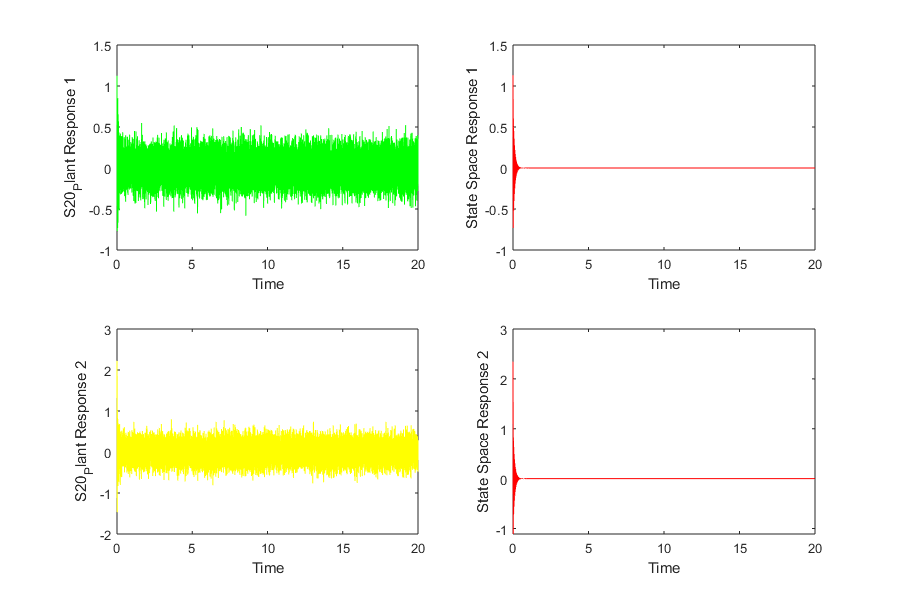

[B_ss1, A_ss1] = ss2tf(A_ss,B_ss,C_ss(1,:),D_ss(1,1));
tf_ss1 = tf(B_ss1, A_ss1, Ts);
[B_ss2, A_ss2] = ss2tf(A_ss,B_ss,C_ss(2,:),D_ss(2,1));
tf_ss2 = tf(B_ss2, A_ss2, Ts);

pulse = [10, zeros(1, N-1)];
response_pulse = s20_plant(pulse);
pulse1 = response_pulse(1,:);
pulse2 = response_pulse(2,:);
figure('Position',[400, 400, 900, 600]);
subplot(2,2,1);
plot(t, pulse1, 'g');
xlabel('Time');
ylabel('S20_Plant Response 1');
subplot(2,2,2);
plot(t, filter(B_ss1, A_ss1, pulse), 'r');
xlabel('Time');
ylabel('State Space Response 1');
subplot(2,2,3);
plot(t, pulse2, 'y');
xlabel('Time');
ylabel('S20_Plant Response 2');
subplot(2,2,4);
plot(t, filter(B_ss2, A_ss2, pulse), 'r');
xlabel('Time');
ylabel('State Space Response 2');

**Section 2**. Before you can develop either a state feedback controller or an output feedback controller, you must next test for controllability and observability. Use your discrete state-space model from the Midterm Project to demonstrate that the open-loop system is completely controllable and completely observable.

disp(rank(ctrb(A_ss,B_ss)));

     5



Since, the rank of the controllability matrix is same as the number of states in the system, the system is completely controllable.

disp(rank(obsv(A_ss,C_ss)));

     5



Since, the rank of the observability matrix is same as the number of states in the system, the system is completely observable.

**Section 3**. Use the Matlab lqr function to design a full state feedback gain matrix for the discrete-time open-loop system. You must design positive definite Q and R weighting matrices to meet the following design requirements:

Simulation Test Conditions:

• Choose zero initial conditions for the model at t=0; however, you are not allowed to reset the state initial conditions back to zero for any time after t=0

• Hold the excitation constant at u=4 for the first 10 ms of the simulation. Note that this first interval of time is required to demonstrate the open-loop response to a constant excitation

• At time t = 10 ms, apply your LQR full state feedback control law to the model, assuming you have complete knowledge of the state vector. Do NOT use a state estimator! You can NOT use any Matlab simulation functions such as lsim.

• Terminate your simulation at t = 30 ms

Mandatory Performance Requirements:

• The control signal must always be bounded within the saturation limits of ±10V

• All responses must always be bounded within the saturation limits of ±10V

• All responses must be settled to within ±0.5V after t = 20 ms.

Q = diag([8000 8000 8000 8000 8000]);
R = 20000;
G = lqr(ss_model, Q, R);
fs_feedback = ss(A_ss - B_ss*G, [] , C_ss - D_ss*G, [] , Ts);
damp(fs_feedback)

                                                                                    
         Pole             Magnitude     Damping       Frequency      Time Constant  
                                                    (rad/seconds)      (seconds)    
                                                                                    
  8.62e-01 + 9.50e-02i     8.67e-01     7.93e-01       3.61e+02         3.50e-03    
  8.62e-01 - 9.50e-02i     8.67e-01     7.93e-01       3.61e+02         3.50e-03    
  3.81e-01 + 7.49e-01i     8.41e-01     1.56e-01       2.23e+03         2.88e-03    
  3.81e-01 - 7.49e-01i     8.41e-01     1.56e-01       2.23e+03         2.88e-03    
  2.00e-01                 2.00e-01     1.00e+00       3.22e+03         3.11e-04    


**Section 4**. Simulate the closed-loop system response of your model with the LQR state feedback control law assuming that you have complete knowledge of the discrete time state vector. Plot the closed-loop time responses up to 30 ms using the Matlab stairs function (read the help file). Your single figure must contain two properly formatted and annotated subplots. The upper subplot will include both outputs and the lower subplot will include the control signal. Use a legend to identify specific signals. You must plot horizontal dashed lines at ±0.5V from 20ms to 30ms to demonstrate that your design meets the convergence requirement.

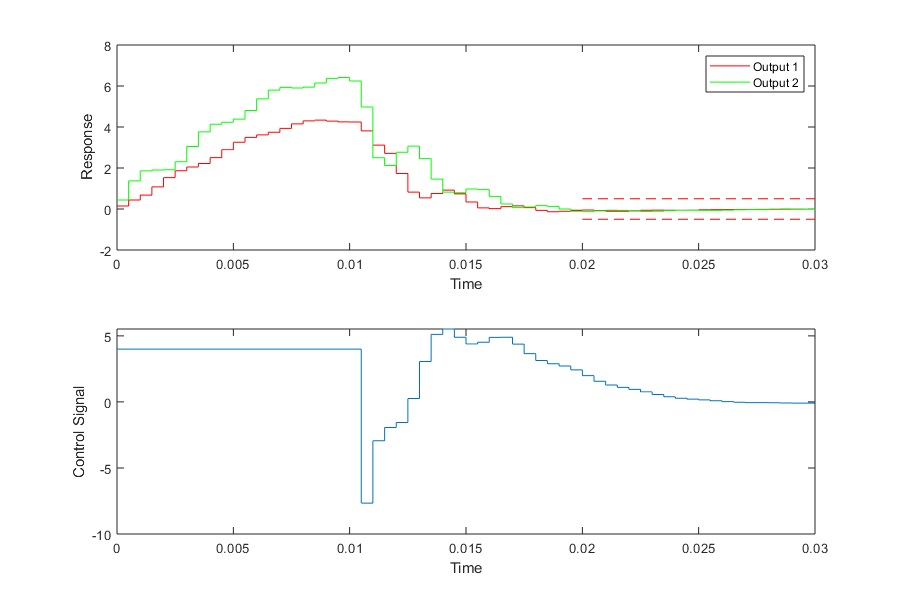

N = 40000;
N_10ms = (10e-3*N)/20 + 1;
N_30ms = (30e-3*N)/20 + 1;
U_Initial = 4*ones(N_10ms, 1);
X_total = zeros(5, N_30ms);
Y_total = zeros(2, N_30ms);

for i = 1:N_10ms
    X_total(:,i+1) = A_ss*X_total(:,i) + B_ss*U_Initial(i,1);
    Y_total(:,i) = C_ss*X_total(:,i) + D_ss*U_Initial(i,1); 
end

t = Ts*[0:N_10ms-1];
figure;

for j = N_10ms:N_30ms - 1
    X_total(:,j+1) = [A_ss - B_ss*G]*X_total(:,j);
    Y_total(:,j+1) = [C_ss - D_ss*G]*X_total(:,j);
end

t_total = Ts*[0:N_30ms-1];
figure('Position',[400, 400, 900, 600]);
subplot(2,1,1);
stairs(t_total, Y_total(1,:), 'r');
hold on;
stairs(t_total, Y_total(2,:), 'g');
hold on;
line([0.02 0.03], [0.5 0.5], 'Color','red','LineStyle','--')
hold on;
line([0.02 0.03], [-0.5 -0.5], 'Color','red','LineStyle','--')
legend('Output 1', 'Output 2');
xlabel('Time');
ylabel('Response')
control_input = [U_Initial' -G*X_total(:, N_10ms:N_30ms - 1)];
subplot(2,1,2);
stairs(t_total, control_input);
xlabel('Time');
ylabel('Control Signal');

zero_input = zeros(1,N);
sensor_noise = s20_plant(zero_input);

**Section 5.** For any practical implementation of full-state feedback control, you must estimate the state vector. Design the Kalman state feedback gains using the following Matlab function call:

[sys,K] = kalman(my_ss_model,QN,RN,NN,'current');

where: QN is a 2x2 process noise covariance matrix, RN is a 2x2 measurement noise covariance matrix, and NN is a 2x2 cross covariance matrix between the process noise and sensor noise. You can estimate the measurement noise covariance matrix using the COV function in Matlab (read the help to learn how). The cross covariance noise matrix NN can be assumed to be zero. As is common in practice, the process noise covariance matrix is the most difficult to determine. It certainly cannot be chosen to be zero, but it should be positive definite. You may choose QN = alpha*eye(2) where alpha is a “tuning” gain that you must select by trial and error. The KALMAN function outputs an LTI object sys as well as the Kalman feedback gains K. You will only use the Kalman feedback gain K!

QN = 5;
NN = 0;
RN = [var(sensor_noise(1,:)) 0; 0 var(sensor_noise(2,:))];
[sys, K] = kalman(ss_model, QN, RN, NN, 'current');

**Section 6**. Construct the discrete-time state-space output feedback controller LTI object as defined above, then generate the closed-loop response of your output feedback controller by inputting the dt_ofc object to the s20_plant.p file with the specified time limits. Plot the closed-loop time responses up to 30 ms using the Matlab stairs function. Your single figure must contain three properly formatted and annotated subplots. The upper subplot will include the actual y1 output, the estimated y1 output, and the error between the actual and estimated y1 outputs. The middle subplot will include the actual y2 output, the estimated y2 output, and the error between the actual and estimated y2 outputs. The lower subplot will include the control signal. Your solution must meet the mandatory performance requirements defined in Section 4. This may require you to run the simulation multiple times. You will next need to develop an output feedback controller and evaluate its performance on the actual system. To do this, you will need to use s20_plant.p with a different call structure. The new call structure is given by:

                                                                                                                   [ y, u, xhat ] = s20_plant( dt_ofc, time );

The input variable dt_ofc is a discrete-time state-space LTI object that you must generate to represent the complete output feedback controller. The discrete time output feedback system is given by the following matrices:

A = A_ss * K*C_ss

B = [(B_ss - K*D_ss) K]

C = -G

D = 0

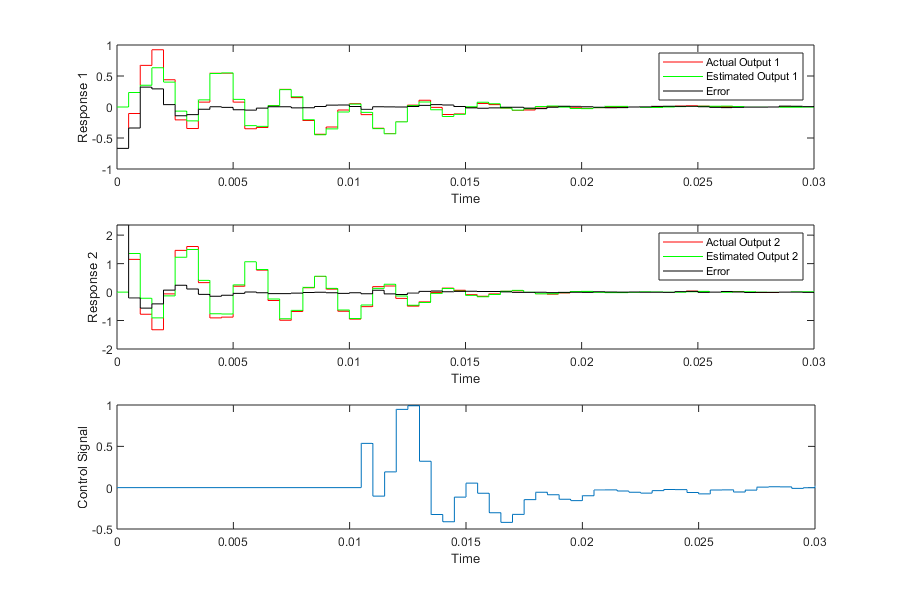

output_feedback_ss = ss(A_ss - K*C_ss, [(B_ss - K*D_ss) K], -G, [], Ts);
[y, u, xhat] = s20_plant(output_feedback_ss, [10e-3, 30e-3]);
yhat = C_ss*xhat + D_ss*u;
figure('Position',[400, 400, 900, 600]);
subplot(3,1,1)
stairs(t_total, y(1,:), 'r');
hold on;
stairs(t_total, yhat(1,:), 'g');
hold on;
stairs(t_total, y(1,:) - yhat(1,:), 'k');
legend('Actual Output 1', 'Estimated Output 1', 'Error');
xlabel('Time');
ylabel('Response 1');
subplot(3,1,2)
stairs(t_total, y(2,:), 'r');
hold on;
stairs(t_total, yhat(2,:), 'g')
hold on;
stairs(t_total, y(2,:) - yhat(2,:), 'k');
legend('Actual Output 2', 'Estimated Output 2', 'Error');
xlabel('Time');
ylabel('Response 2');
subplot(3,1,3);
stairs(t_total, u);
xlabel('Time');
ylabel('Control Signal');

As we can see in the above graphs, the error between the actual output and estimated output by the s20_plant converges to near zero within the first 10 ms of the simulation. This indicates that the observer works correctly. The graphs also satisfy all the mandatory performance requirements mentioned in Section 4.